# **MECH 103**

**HomeWork 2: Abdulla Al Ameri**

## THE FIRST PROBLE: The first problem deals with a charge on capacitor in a circuit and how it changes with respect to time (t)


clear
clc 

%Defining variables:

qnot = 10

qnot = 10

%Intial charge on the capacitor.


R = 60

R = 60

%Resistance


C = 0.00005

C = 5.0000e-05

C2 = 0.0005

C2 = 5.0000e-04

%Capacitance -we're looking at C with two
%Different capacitances.


L = 9

L = 9

%Inductance


t = linspace(0,0.8,100)

t =          0    0.0081    0.0162    0.0242    0.0323    0.0404    0.0485    0.0566    0.0646    0.0727    0.0808    0.0889    0.0970    0.1051    0.1131    0.1212    0.1293    0.1374    0.1455    0.1535    0.1616    0.1697    0.1778    0.1859    0.1939    0.2020    0.2101    0.2182    0.2263    0.2343    0.2424    0.2505    0.2586    0.2667    0.2747    0.2828    0.2909    0.2990    0.3071    0.3152    0.3232    0.3313    0.3394    0.3475    0.3556    0.3636    0.3717    0.3798    0.3879    0.3960


%The time we're interested in is between 0 seconds
%and 0.8 seconds, linspace function will put a 100
%number going from 0 to 0.8, so that way we have enough
%number of variables to get more accurate graph.


z = ((-R).*t)/(2.*L)

z =          0   -0.0269   -0.0539   -0.0808   -0.1077   -0.1347   -0.1616   -0.1886   -0.2155   -0.2424   -0.2694   -0.2963   -0.3232   -0.3502   -0.3771   -0.4040   -0.4310   -0.4579   -0.4848   -0.5118   -0.5387   -0.5657   -0.5926   -0.6195   -0.6465   -0.6734   -0.7003   -0.7273   -0.7542   -0.7811   -0.8081   -0.8350   -0.8620   -0.8889   -0.9158   -0.9428   -0.9697   -0.9966   -1.0236   -1.0505   -1.0774   -1.1044   -1.1313   -1.1582   -1.1852   -1.2121   -1.2391   -1.2660   -1.2929   -1.3199


%The exponent power


u = ( (1/(L.*C)) - (R/(2.*L)).^2 )

u = 2.2111e+03

u2 = ( (1/(L.*C2)) - (R/(2.*L)).^2 )

u2 = 211.1111


%The Radicand- Note: u2 is with respect to
%the second capacitance.


QAT = qnot .* exp (z) .* cos (sqrt(u).*t)

QAT =    10.0000    9.0399    6.8685    3.8523    0.4566   -2.8247   -5.5397   -7.3391   -8.0198   -7.5455   -6.0429   -3.7757   -1.1005    1.5880    3.9139    5.5716    6.3646    6.2278    5.2289    3.5526    1.4684   -0.7114   -2.6777   -4.1671   -4.9967   -5.0855   -4.4598   -3.2445   -1.6401    0.1091    1.7513    3.0630    3.8783    4.1096    3.7552    2.8953    1.6763    0.2874   -1.0689   -2.2048   -2.9734   -3.2867   -3.1249   -2.5354   -1.6229   -0.5318    0.5763    1.5458    2.2488    2.6010


% The equation for charge in capacitor as function of time

QAT2 = qnot .* exp (z) .* cos (sqrt(u2).*t)

QAT2 =    10.0000    9.6672    9.2155    8.6574    8.0065    7.2767    6.4825    5.6385    4.7592    3.8588    2.9513    2.0497    1.1664    0.3131   -0.5000   -1.2633   -1.9688   -2.6095   -3.1798   -3.6753   -4.0929   -4.4309   -4.6887   -4.8668   -4.9668   -4.9916   -4.9446   -4.8303   -4.6538   -4.4210   -4.1379   -3.8114   -3.4481   -3.0553   -2.6400   -2.2092   -1.7698   -1.3285   -0.8916   -0.4650   -0.0542    0.3357    0.7005    1.0363    1.3399    1.6086    1.8405    2.0343    2.1892    2.3051


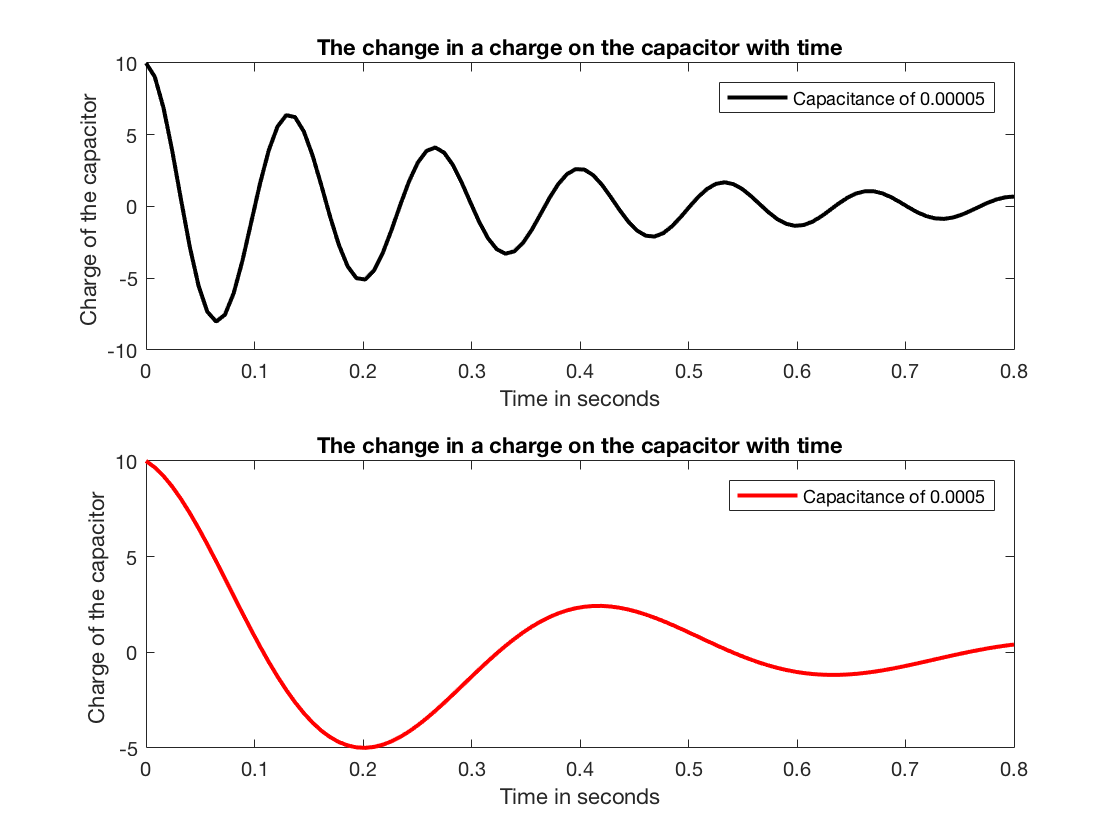

% The equation for charge in capacitor as function of time
% with a 0.0005 capacitance instead of 0.00005

%GRAPHING%

%We're using subplot function to have two different plots
%on the same graph, (2,1,x), 2,1 means 2 raws and
%one column, and x is the order of the graph.


subplot (2,1,1);

x=t; % Defining our x axis for graph 1
y1=QAT; % Defining our y axis for graph 1

plot (x,y1,'k-','linewidth',2)
%plotting t with respect to QAT with black straight
%lines of width 2.

xlabel('Time in seconds')
ylabel('Charge of the capacitor ')

%Labeling AXIS.


title('The change in a charge on the capacitor with time')
legend('Capacitance of 0.00005')
%Adding title and the legend


%SECOND Subplot%

subplot (2,1,2);

x=t; % Defining our x axis for graph 2
y2=QAT2; % Defining our y axis for graph 2

plot(x,y2,'r-','linewidth',2)
%plotting t with respect to QAT2 with red straight
%lines of width 2.

xlabel('Time in seconds')
ylabel('Charge of the capacitor ')
%Labeling AXIS.

title('The change in a charge on the capacitor with time')
legend('Capacitance of 0.0005')

%Adding title and the legend




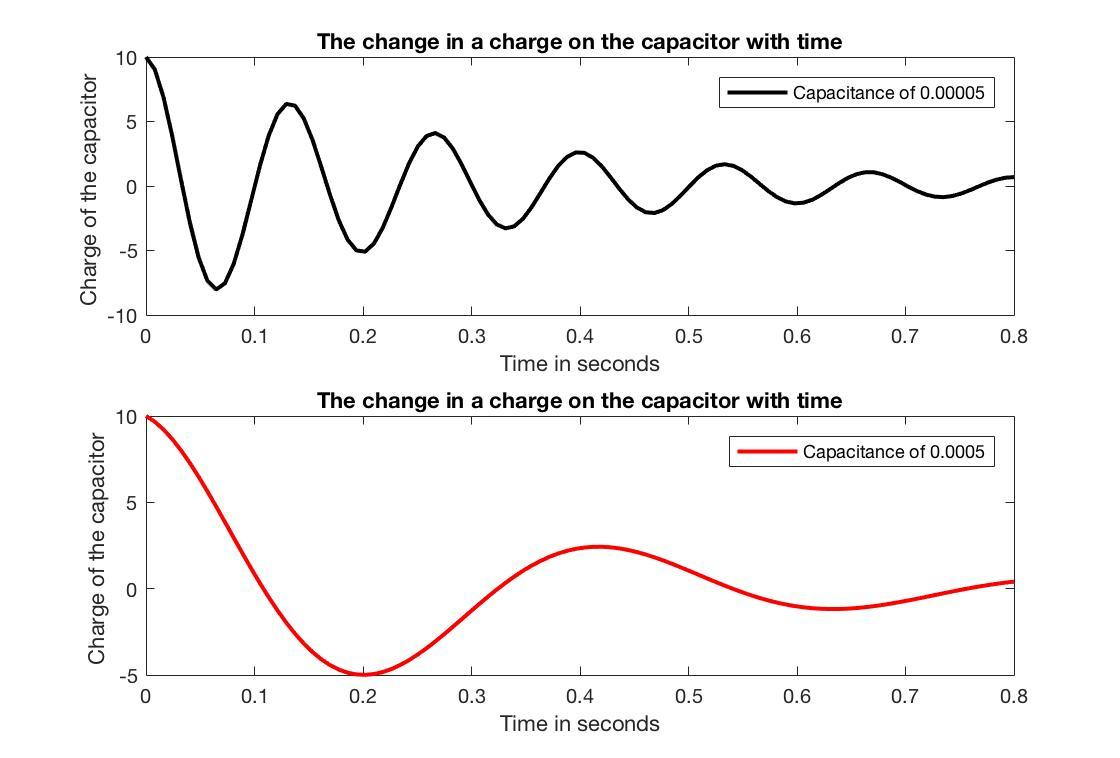

## THE SECOND PROBLEM: We're comparing the data of concentration vs time for photodegradation of aqueous bromine



clear
clc 

%Defining Variables:

t = 0:10:70 %Time

t =      0    10    20    30    40    50    60    70


c = 4.84*exp(-0.034*t) %Concentration

c =     4.8400    3.4450    2.4520    1.7453    1.2422    0.8842    0.6293    0.4479



TheFunction = plot (t,c,'g--','linewidth',2)

ONE =   Line with properties:

              Color: [0 1 0]
          LineStyle: '--'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 10 20 30 40 50 60 70]
              YData: [4.8400 3.4450 2.4520 1.7453 1.2422 0.8842 0.6293 0.4479]
              ZData: [1×0 double]

  Show all properties


%Plotting the concentration function with respect to time.


hold on %Function to add other graphs on the same graph

DataPoint = plot (t(2:7),c(2:7),'rd')

TWO =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'diamond'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [10 20 30 40 50 60]
              YData: [3.4450 2.4520 1.7453 1.2422 0.8842 0.6293]
              ZData: [1×0 double]

  Show all properties


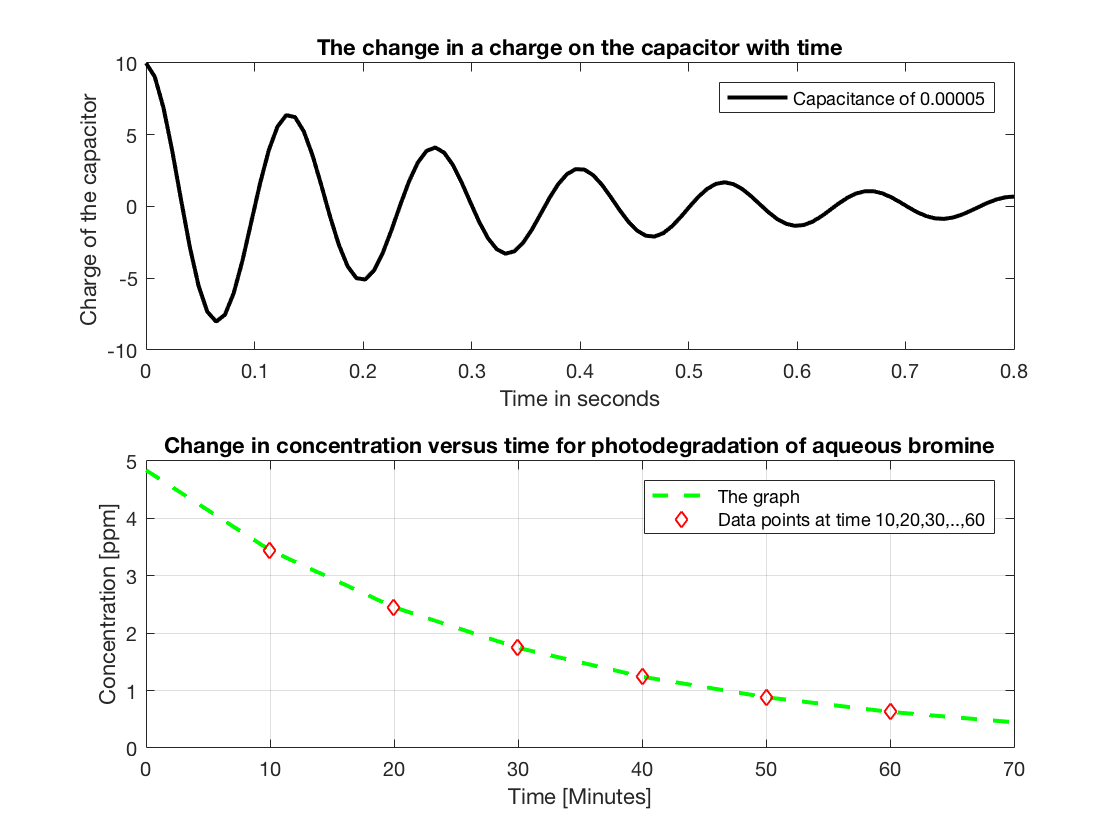

%Plotting a specific data points with red dimonds shape on the same graph

hold off %Now we're done adding graphs

legend('The graph','Data points at time 10,20,30,..,60')
%Adding legend box and naming them.


%Editing the graph properties.

grid
xlabel('Time [Minutes]')
ylabel('Concentration [ppm]')
title('Change in concentration versus time for photodegradation of aqueous bromine')